# F15 ordinær eksamen opgave 2

# Opgave a og b

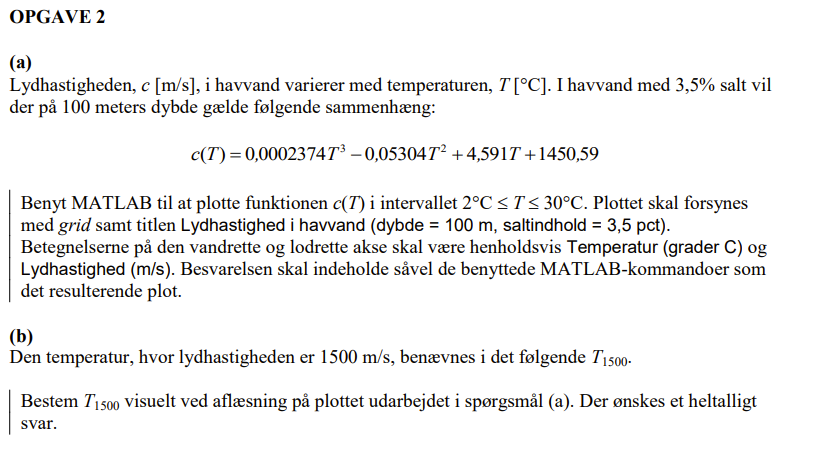

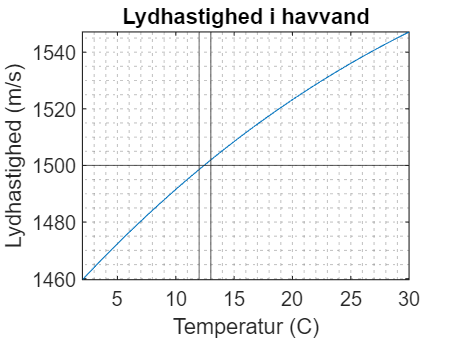

cT = @(T) 0.0002374*T.^3 - 0.05304*T.^2 + 4.593*T + 1450.69;


fplot(cT, [2, 30]), grid("minor"), title("Lydhastighed i havvand")
xlabel("Temperatur (C)"), ylabel("Lydhastighed (m/s)")

yline(1500), xline(12), xline(13)


fprintf("Svar til b) 12 grader")

Svar til b) 12 grader

# Opgave C

f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
Tl = 10; % Nedre intervalendepunkt (grader C)
Tu = 15; % Øvre intervalendepunkt (grader C)
es = 0.01; % Ønsket nøjagtighed af rod (%)
maksit = 20; % Maksimal antal iterationer
it = 0; % Startværdi for iterationstælleren it
while 1
    Tr = (Tl + Tu)/2;
    ea = abs(Tr-Tl)/Tr*100;
    it = it + 1;

    if f(Tl)*f(Tr) > 0
        Tl = Tr;

    elseif f(Tl)*f(Tr) < 0
        Tu = Tr;

    else
        ea = 0;

    end

    if ea <= es || it >= maksit
        break
    end
end

fprintf("Opgave c")

Opgave c

T1500 = Tr

T1500 = 12.4548

ea

ea = 0.0098

it

it = 12

ea er relative fejl i estimeringen, som ønskes lavere end es. it er antallet af loops (iterationer) som scriptet har kørt for at opnå den ønskede præcision. While loopet kører så længe det er "true" (1), og stopper efter n iterationer når betingelserne er nået.

# Opgave e og f

f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;

fprintf("Opgave e")

Opgave e

fzero(f, [2, 32])

ans = 12.4545



fprintf("Opgave f")

Opgave f

%ff = 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
r = roots([0.0002374, -0.05304, 4.591, -49.41])

r = 1.0e+02 *

   1.0548 + 0.7473i
   1.0548 - 0.7473i
   0.1245 + 0.0000i


Her ses det at fzero giver et mere præcist svar, end bisektionsmetoden, da funktionen returnerer den eksakte værdi, hvorimod bisektion giver et svar givet en ønsket præcision.

roots funktionen kræver et f^n + f^n-1..  polynomie, der giver n løsninger, hvor vi her har et 3. grads polynomie, som funktionen løser for alle mulige løsninger - hvor det ses det rigtigte svar er den tredje løsning.

# Opgave 2 reeksamen 2015

Opgave 2 a) til c)

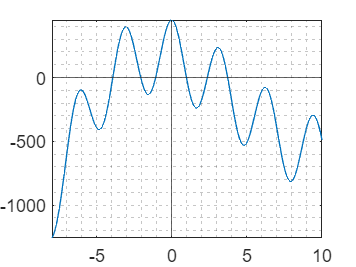

% Opgave a

f = @(x) 300.*cos(2.*x) + x.^3 - 14.*x.^2 - 36.*x + 150;

int = [-8, 10];

fplot(f, int), grid("minor"), xline(0), yline(0)

Ud fra plottet aflæses der i alt 6 rødder

- -4, 0

- -2, 0

- -1, 0

- 1, 0

- 2.2, 0

- 3.8, 0

% Opgave b

f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150;

for x = -100:100
    if f(x)*f(x+1) < f(x)
        disp([x,x+1])
    end
end

    -4    -3

    -3    -2

    -2    -1

     0     1

     2     3

     3     4

    15    16



For loopet tjekker om der er fortegnsskifte i et [x, x+1] interval, og hvis der er det, bliver if-betingelsen opfyldt, og der printes et interval hvori fortegnsskiftet finder sted. Ift. svarene i a), ses det er det stemmer, er der er fortegnsskifte ved ca. punkt 4, og for-loppet angiver der er fortegnsskifte et sted mellem -4 og -3. Det samme gælder de andre punkter.

% Opgave c

% Forslag 1
xl = 1; xu = 3;
bisect(f, xl, xu, 0.01)

root = 2.3551

fx = -0.0274

ea = 0.0052

iter = 14

ans = 2.3551


% Forslag 2
xl = 1.75; xu = 2.25;
bisect(f, xl, xu, 0.01)

Error using bisect
no sign
change

Det første forslag er bedst, da det har det bredeste interval at søge i. Da det ikke er tydeligt ud fra grafen, præcist hvor den skærer omkring x = 2, er forslag 2 intervallet for smalt. Havde man en bedre ide om hvor roden lå, kunne det være fint.

Ud fra undersøgelse med bisektions-funktionen fra undervisningen, sker det nemlig at intervallet i forslag 2 ikke er bredt nok, til at fange fortegnsskiftet